# Reanalysis of Stefanini *et al.* 2020

The neural data is taken at 5Hz.

top_dir = '../fabio_data';

behavior = {'dhpc08_behavior.txt', 'dhpc09_behavior.txt', 'dhpc10_behavior.txt'};
neural_data = {'dhpc08_cnmfe_spikes.txt', 'dhpc09_cnmfe.mat', 'dhpc10_cnmfe.mat'};

sess = cell(1,3);
for sess_idx = 1:3
    f_ = @(x) fullfile(top_dir, x);
    sess{sess_idx} = OpenField(f_(behavior{sess_idx}), f_(neural_data{sess_idx}));
end

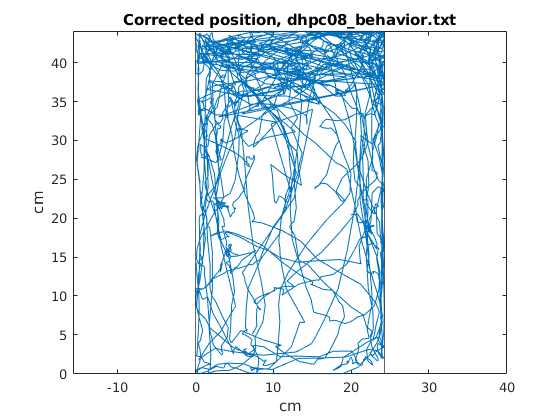

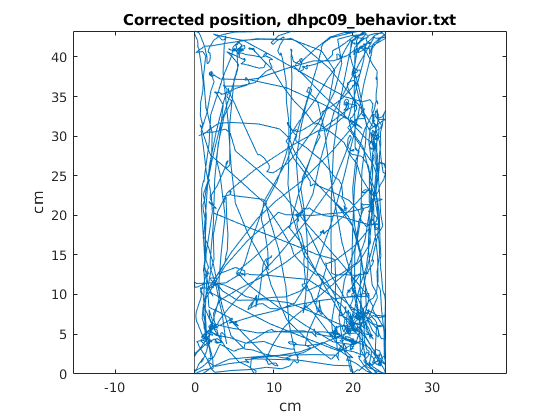

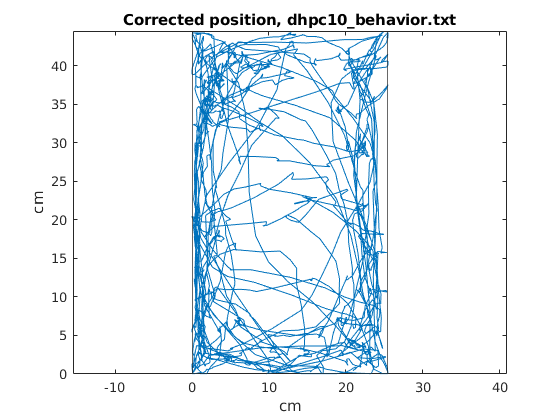

for i = 1:3
    figure;
    sess{i}.plot_ortho_pos;
    title(['Corrected position, ' esc(behavior{i})]);
    xlabel 'cm'
    ylabel 'cm'
end

Non continuous data decoding (like our shuffling method):

[dec_error, me, me_s] = sess.decode(false, false);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 15).


fprintf('Decoding error was %f (cm) +- %f\n', me, me_s);

Decoding error was 18.575156 (cm) +- 10.654511


[dec_error_shuf, me_shuf, me_s_shuf] = sess.decode(true, false);
fprintf('Shuffled decoding error was %f (cm) +- %f\n', me_shuf, me_s_shuf);

Shuffled decoding error was 8.172459 (cm) +- 11.799157


Continuous data decoding (like Stefanini's shuffling method):

[fs_err, fs_std, fs_err_shuf, fs_std_shuf] = deal(zeros(1,3));
for i = 1:3
    [dec_error, me, me_s, fs_err(i), fs_std(i)] = sess{i}.decode(false, true);
    fprintf('Decoding error was %f (cm) +- %f\n', me, me_s);
    fprintf('Decoding mean median was %f (cm) +- %f\n', fs_err(i), fs_std(i));
    [dec_error_shuf, me_shuf, me_s_shuf, fs_err_shuf(i), fs_std_shuf(i)] = sess{i}.decode(true, true);
    fprintf('Shuffled decoding error was %f (cm) +- %f\n', me_shuf, me_s_shuf);
    fprintf('Shuffled mean median was %f (cm) +- %f\n', fs_err_shuf(i), fs_std_shuf(i));
end

Decoding error was 11.396841 (cm) +- 9.613038


Decoding mean median was 8.294787 (cm) +- 2.005095


Shuffled decoding error was 8.131889 (cm) +- 8.619765


Shuffled mean median was 4.846951 (cm) +- 1.180220


Decoding error was 12.842242 (cm) +- 10.227749


Decoding mean median was 10.702024 (cm) +- 2.754665


Shuffled decoding error was 9.867132 (cm) +- 10.116791


Shuffled mean median was 6.141634 (cm) +- 2.564054


Decoding error was 14.361608 (cm) +- 10.251081


Decoding mean median was 12.414584 (cm) +- 2.587942


Shuffled decoding error was 9.045003 (cm) +- 9.051638


Shuffled mean median was 5.541388 (cm) +- 1.346977


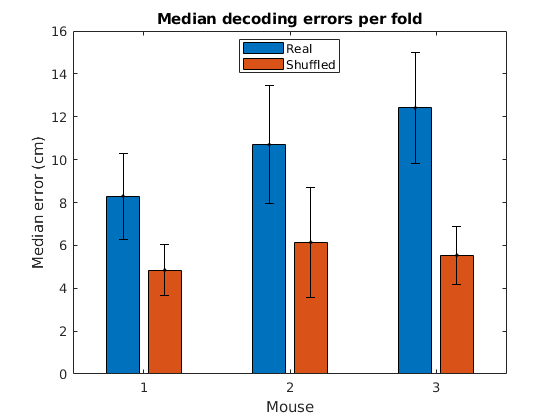

figure;
errnbar([fs_err; fs_err_shuf].', [fs_std; fs_std_shuf].');
title 'Median decoding errors per fold'
legend Real Shuffled Location best
ylabel 'Median error (cm)'
xlabel 'Mouse'

t_ = tic;
res = cell(1,3);
for i = 1:3
    res{i} = sess{i}.decode_all;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 15).


toc(t_)

Elapsed time is 218.477511 seconds.


[err_mat, err_errb_mat] = deal(zeros(3,3));
for i = 1:3
    err_mat(i,1) = mean(res{i}.fs_metric_real);
    err_mat(i,2) = mean(res{i}.fs_metric_shuf);
    err_mat(i,3) = mean(res{i}.fs_metric_diag);
    
    err_errb_mat(i,1) = std(res{i}.fs_metric_real);
    err_errb_mat(i,2) = std(res{i}.fs_metric_shuf);
    err_errb_mat(i,3) = std(res{i}.fs_metric_diag);
end

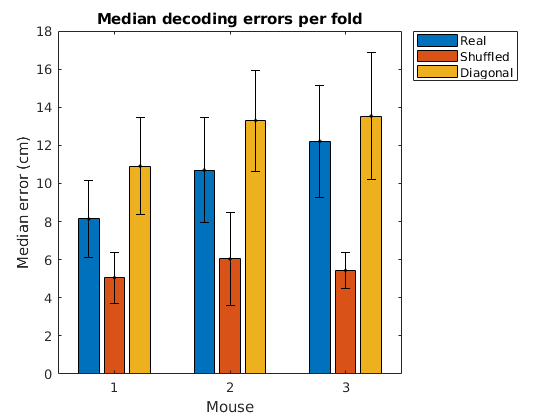

figure;
errnbar(err_mat, err_errb_mat);
title 'Median decoding errors per fold'
legend Real Shuffled Diagonal Location bestoutside
ylabel 'Median error (cm)'
xlabel 'Mouse'

for i = 1:3
    res_spikeshuf{i} = sess{i}.decode_spikeshuf(false);
    res_spikeshuf_auto{i} = sess{i}.decode_spikeshuf(true);
end

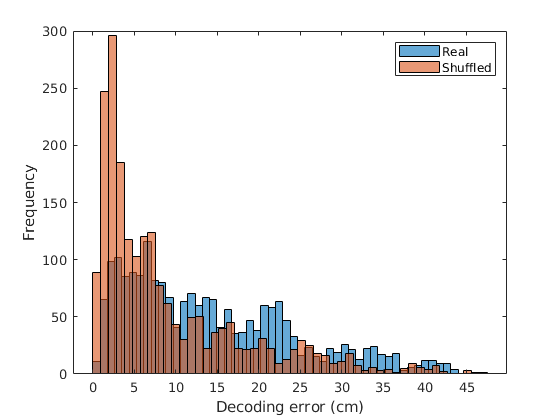

figure;
histogram(dec_error, 50);
hold on;
histogram(dec_error_shuf, 50);
xlabel 'Decoding error (cm)'
ylabel 'Frequency'
legend Real Shuffled

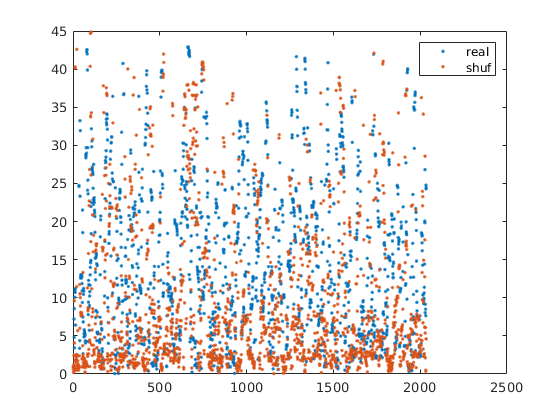

figure;
plot(dec_error, '.'); hold on;
plot(dec_error_shuf, '.');
legend real shuf

## Using a continuous decoder

[X_cont, y_cont, ks] = sess.get_continuous_dataset;
X_cont_shuf = fshuffle(X_cont, ks, false);
X_cont_shuf_auto = fshuffle(X_cont, ks, true);

[real_e, real_nn_rms, real_nn_val_rms, real_nn_train_rms] = two_layer_net(X_cont, y_cont);
[shuf_e, shuf_nn_rms, shuf_nn_val_rms, shuf_nn_train_rms] = two_layer_net(X_cont_shuf, y_cont);
[autoshuf_e, autoshuf_nn_rms, autoshuf_nn_val_rms, autoshuf_nn_train_rms] = two_layer_net(X_cont_shuf_auto, y_cont);

tab(1,1) = real_nn_rms;
tab(2,1) = real_nn_val_rms;
tab(3,1) = real_nn_train_rms;

tab(1,2) = shuf_nn_rms;
tab(2,2) = shuf_nn_val_rms;
tab(3,2) = shuf_nn_train_rms;

tab(1,3) = autoshuf_nn_rms;
tab(2,3) = autoshuf_nn_val_rms;
tab(3,3) = autoshuf_nn_train_rms;

tab = array2table(tab, "RowNames",{'Test', 'Validation', 'Train'}, "VariableNames",{'Real', 'Shuf', 'Autoshuf'})

tab = 3×3 table
                   Real      Shuf     Autoshuf
                  ______    ______    ________

    Test          11.185    9.7879     11.321 
    Validation       NaN       NaN        NaN 
    Train         9.6085    9.2521     9.6704 


real_dist_e = vecnorm(real_e);
shuf_dist_e = vecnorm(shuf_e);

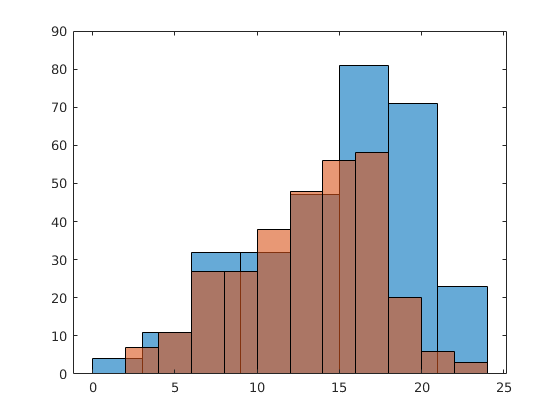

figure;
histogram(real_dist_e(end-300:end));
hold on;
histogram(shuf_dist_e(end-300:end));

real_test_median = median(real_dist_e(end-300:end))

real_test_median = 16.0114

shuf_test_median = median(shuf_dist_e(end-300:end))

shuf_test_median = 13.7401